clear;clc;
radius = 0.103;
N = 126;
mu = 4*pi*10^-7;

Ri = [50 70 100 1000 300 0 40 60 20 100]'

Ri =           50
          70
         100
        1000
         300
           0
          40
          60
          20
         100


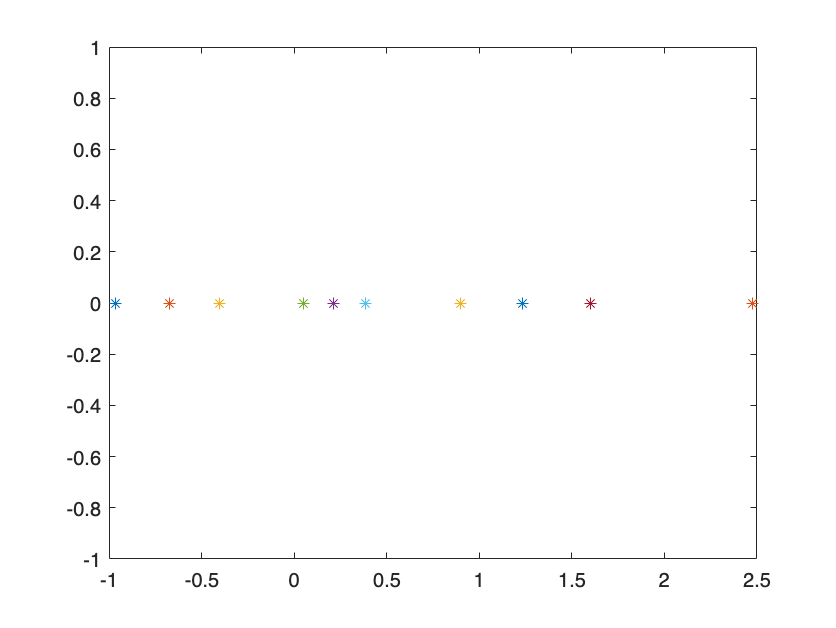

I = [-67 -50 -37 -4 -13 0 40 29 67 18];
i = i.*10^-3;
theta=[-44 -34 -22 12 3 21 58 51 68 42];
tai = tand(theta.*1);

Bi =(8* mu*N*i)./(radius*sqrt(125));
hold off;
plot(tai, Bi, "*"); hold on;


p = polyfit(tai,Bi,1);

Error using polyfit
The first two inputs must have the same number of elements.


plot(tai,p(1)*tai+p(2),"-");
Bv = p(1);
Bh = -p(2);
Be = sqrt(BV);
